# Machine Learning with MATLAB

Digital Twin & Automation

# Decision Tree

## Data Acquisition

### Dataset 1:  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear

%% Train
load("../3_MachingLearning/CWRU_Datas/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);

%% Test
load("../3_MachingLearning/CWRU_Datas/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);


#### Plot Test Data

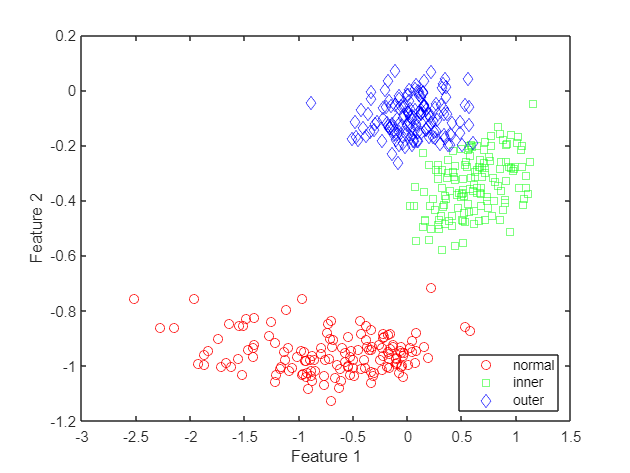

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2')

## Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

# **Decision Tree**

### Fit decision Tree

t = fitctree(X, Y,'PredictorNames',{'SV' 'IF'});

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

tResubErr = resubLoss(t)

tResubErr = 0.0023

**Confusion matrix** on the training set

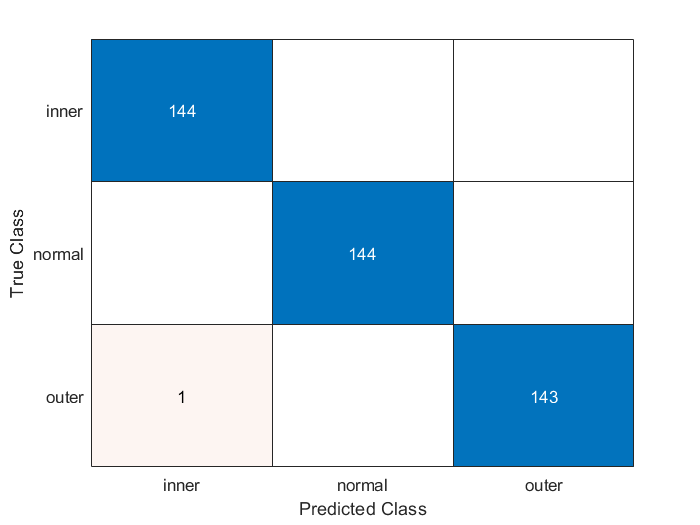

tClass = resubPredict(t);
figure
tResubCM = confusionchart(Y,tClass);

**Misclassification Plot**

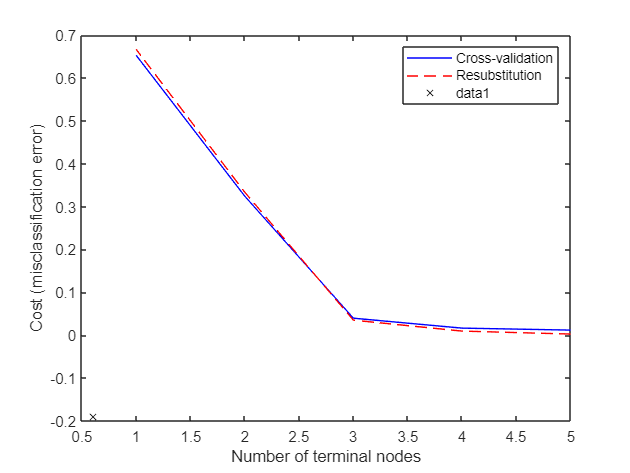

figure(f)
bad = ~strcmp(tClass,Y);
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;

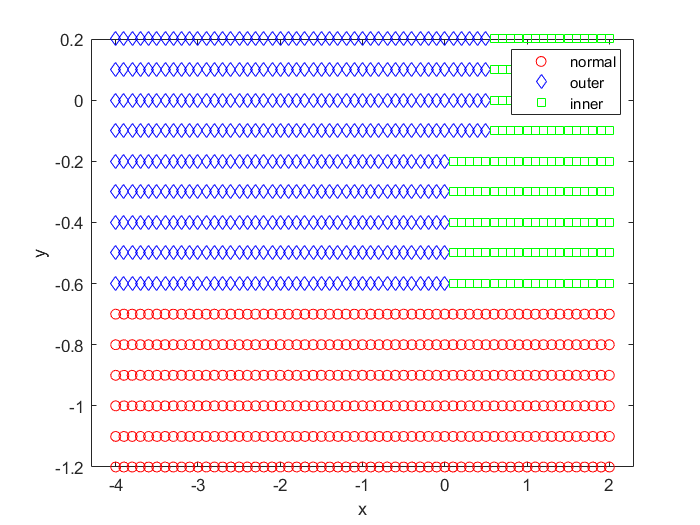

% Visualize Separation regions 
[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
[grpname,node] = predict(t,[x y]);
gscatter(x,y,grpname,'rbg','ods')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvt = crossval(t,'CVPartition',cv);
tCVErr = kfoldLoss(cvt)

tCVErr = 0.0069

**visualize the decision tree **

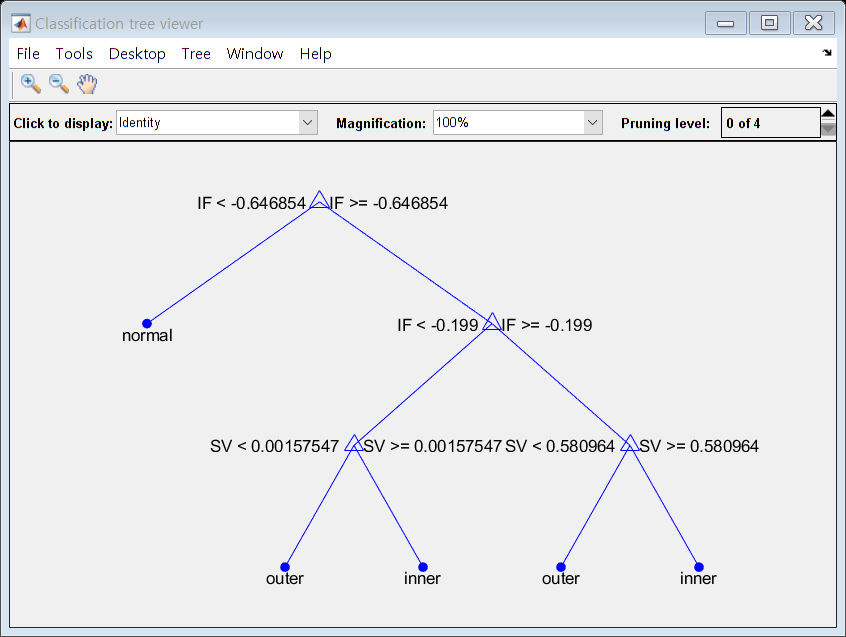

view(t,'Mode','graph');

**Prune tree nodes to enhance result**

- First compute the resubstitution error for various subsets of the original tree. 

- Then compute the cross-validation error for these sub-trees. 

resubcost = resubLoss(t,'Subtrees','all')

resubcost =     0.0023
    0.0093
    0.0347
    0.3333
    0.6667


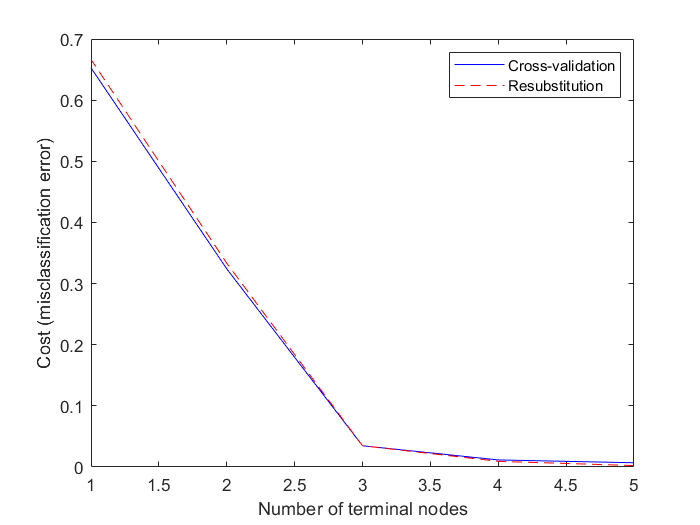

[cost,secost,ntermnodes,bestlevel] = cvloss(t,'Subtrees','all');

plot(ntermnodes,cost,'b-', ntermnodes,resubcost,'r--')
xlabel('Number of terminal nodes');
ylabel('Cost (misclassification error)')
legend('Cross-validation','Resubstitution')

% Prune Tree Levels
pt = prune(t,'Level',bestlevel);
cost(bestlevel+1)

ans = 0.0069

view(pt,'Mode','graph')

# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

**Features**

% Example

feature1 = "kv";
feature2 = "mf";
feature3 = "cf";

X(:, 1) = table2array(glob_all_train(:, feature1));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, feature2));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, feature3));       % Marginal-Factor

N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);

yCate = categorical(Y);
idx_inner = yCate == 'inner';
idx_outer = yCate == 'outer';
idx_normal = yCate == 'normal';

Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Xtest(:, 3) = table2array(glob_all_test(:, feature3));

Plot the test and train results in 3D graph.

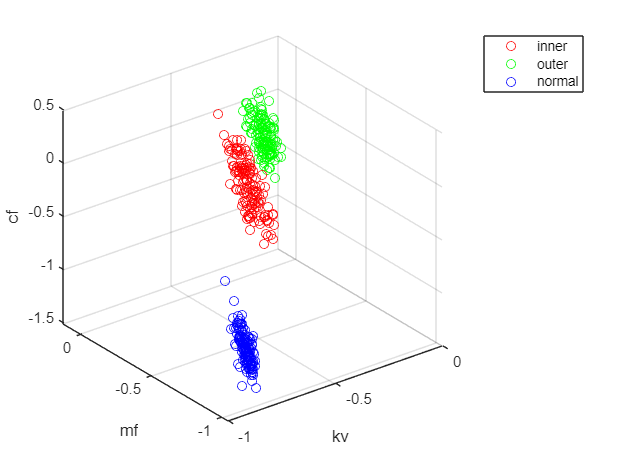

figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
grid on
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','outer','normal')
hold off

## **Crossfold validation**

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-fold cross validation partition
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

## **Decision tree & Confusion matrix**

Mdl = fitctree(X, Y,'PredictorNames',{'KV' 'MF' 'CF'});

MdlResubErr = resubLoss(Mdl)

MdlResubErr = 0

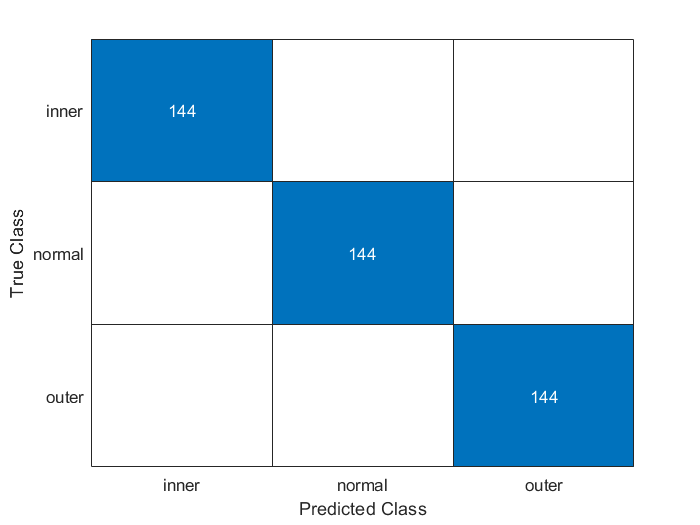

MdlClass = resubPredict(Mdl);
figure
MdlResubCM = confusionchart(Y,MdlClass);

## Visualization

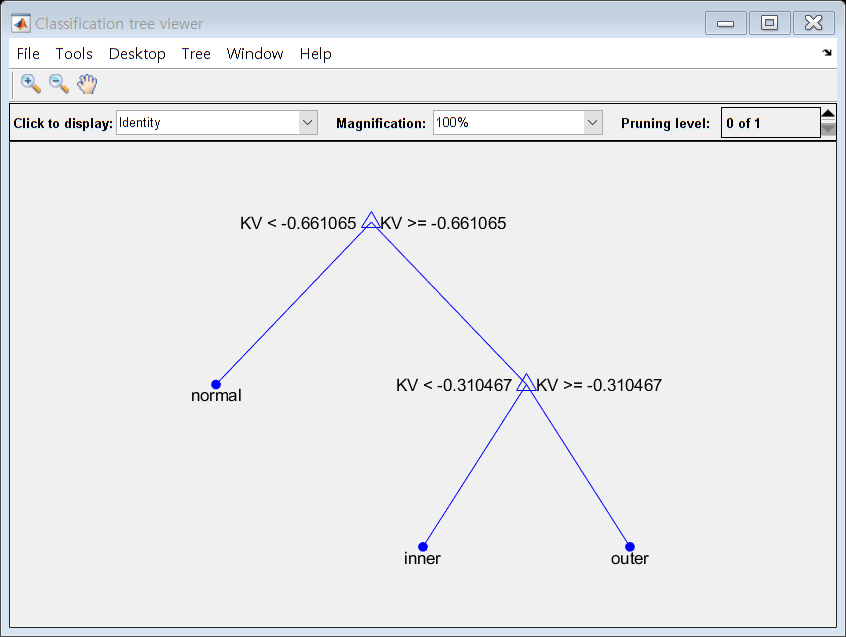

view(Mdl,'Mode','graph');

## Exercise 2 

Compare performance with other classification 

- One reason why decision trees can be faster than other algorithms is because they are a non-parametric method, meaning they make no assumptions about the distribution of the data. This allows them to handle complex relationships between variables without requiring a large number of parameters, which can be computationally expensive to estimate.

- The Gini index and entropy are two common metrics used to evaluate the quality of a split in a decision tree. The Gini index measures the probability of misclassifying a randomly chosen element if it were randomly labeled according to the distribution of classes in a given node. The entropy measures the amount of information contained in a set of data. These metrics are used to calculate the information gain at each split, which is used to choose the best feature to split on.

## Exercise 3 

 How can you apply random forest in Matlab?

- Definition of random forest

              Random Forest is a machine learning algorithm that creates a collection of decision tree models and combines their predictions to make an overall prediction.

- Bagging method is used to train each decision tree model.

- Procedure

**Implementation of random forest**

t = templateTree('NumVariablesToSample','all');
% Random forest modle을 훈련
Mdl = fitcensemble(X, Y, 'Method', 'Bag', 'NumLearningCycles', 100, 'Learners', t);

view(Mdl,'Mode','graph');

Error using view
When specified as a graphics object, first argument must be one or more axes objects.


result = predict(Mdl, Xtest);

figure
MdlResubCM = confusionchart(Ytest, result);